clear; clc
n = 1;
xx = 100:100:100000;
for i = xx
    aa = convergence_halton(i);
    halton_results(n, 1) = aa(1,1);
    halton_results(n, 2) = aa(1,2);
    halton_results(n, 3) = aa(2,1);
    halton_results(n, 4) = aa(2,2);
    bb = convergence_lhs(i);
    lhs_results(n, 1) = bb(1,1);
    lhs_results(n, 2) = bb(1,2);
    lhs_results(n, 3) = bb(2,1);
    lhs_results(n, 4) = bb(2,2);
    n = n+1;
end

convTime_lhs = zeros(1,4);
convTime_halton = zeros(1,4);
for i = 1:length(halton_results)-1
    for j = 1:4
        a = halton_results(i, j);
        ap = halton_results(i+1, j);
        conv_rate_halton(i, j) = (ap - a)/a;
        b = lhs_results(i, j);
        bp = lhs_results(i+1, j);
        conv_rate_lhs(i,j) = (bp-b)/b;
    end
end
for j = 1 :4
    n = 1; m = 1;
    for i = 1:length(halton_results)-1    
        if i > 10 
            a = mean(abs(conv_rate_halton(i-10:i, j)));
            % Convergence is set as 1% percent diff for last 10 results
            if a <= 0.01 && n == 1 
                convTime_halton(j) = i;
                n = n+1;
            end
            b = mean(abs(conv_rate_lhs(i-10:i, j)));
            if b <= 0.01 && m == 1
                convTime_lhs(j) = i;
                m = m+1;
            end
        end
    end
end
convTime_lhs

convTime_lhs =    371   946   352   946


convTime_halton

convTime_halton =     23    39    12    21



NumSimConv_lhs = 1000 + (convTime_lhs-1)*100

NumSimConv_lhs =        38000       95500       36100       95500


NumSimConv_halton = 1000 + (convTime_halton-1)*100

NumSimConv_halton =         3200        4800        2100        3000


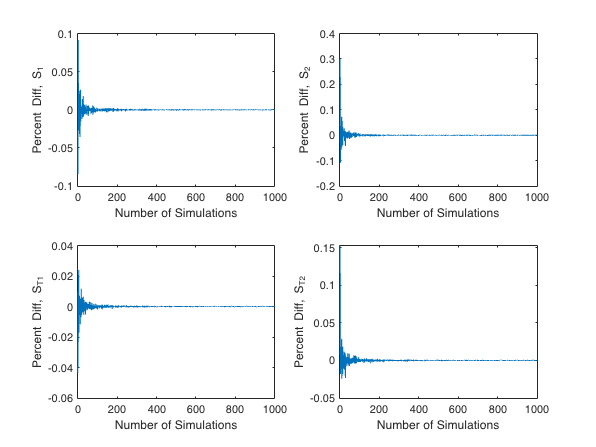


% Plot of convergence rate of sobal indices
figure
subplot(2,2,1)
plot(1:length(halton_results)-1, conv_rate_halton(:, 1))
ylabel('Percent Diff, S_1')
xlabel('Number of Simulations')
subplot(2,2,2)
plot(1:length(halton_results)-1, conv_rate_halton(:, 2))
ylabel('Percent Diff, S_2')
xlabel('Number of Simulations')
subplot(2,2,3)
plot(1:length(halton_results)-1, conv_rate_halton(:, 3))
ylabel('Percent Diff, S_{T1}')
xlabel('Number of Simulations')
subplot(2,2,4)
plot(1:length(halton_results)-1, conv_rate_halton(:, 4))
ylabel('Percent Diff, S_{T2}')
xlabel('Number of Simulations')


figure 
subplot(2,2,1)
plot(1:length(halton_results)-1, conv_rate_lhs(:, 1))
ylabel('Percent Diff, S_1')
xlabel('Number of Simulations')
subplot(2,2,2)
plot(1:length(halton_results)-1, conv_rate_lhs(:, 2))
ylabel('Percent Diff, S_2')
xlabel('Number of Simulations')
subplot(2,2,3)
plot(1:length(halton_results)-1, conv_rate_lhs(:, 3))
ylabel('Percent Diff, S_{T1}')
xlabel('Number of Simulations')
subplot(2,2,4)
plot(1:length(halton_results)-1, conv_rate_lhs(:, 4))
ylabel('Percent Diff, S_{T2}')
xlabel('Number of Simulations')


% Plot of sobal indices values vs number of simulations
figure
title('Halton Sequance')
subplot(2,2,1)
plot(xx, halton_results(:,1))
ylabel('S_1')
xlabel('Number of Simulations')
subplot(2,2,2)
plot(xx, halton_results(:,2))
ylabel('S_2')
xlabel('Number of Simulations')
subplot(2,2,3)
plot(xx, halton_results(:,3))
ylabel('S_{T1}')
xlabel('Number of Simulations')
subplot(2,2,4)
plot(xx, halton_results(:,4))
ylabel('S_{T2}')
xlabel('Number of Simulations')


figure
subplot(2,2,1)
plot(xx, lhs_results(:,1))
ylabel('S_1')
xlabel('Number of Simulations')
subplot(2,2,2)
plot(xx, lhs_results(:,2))
ylabel('S_2')
xlabel('Number of Simulations')
subplot(2,2,3)
plot(xx, lhs_results(:,3))
ylabel('S_{T1}')
xlabel('Number of Simulations')
subplot(2,2,4)
plot(xx, lhs_results(:,4))
ylabel('S_{T2}')
xlabel('Number of Simulations')

function indices = convergence_halton(M)
phi = -18.41;
h = 0.00191;

param1 = [0.5 1.5]*phi;
param2 = [0.5 1.5]*h;

p = 2;
A = zeros(M, 2);
B = zeros(M, 2);
halton_set = net(haltonset(4), M);

A(:,1) = param1(1) + (param1(2) - param1(1)).*halton_set(:, 1);
A(:,2) = param2(1) + (param2(2) - param2(1)).*halton_set(:, 2);

B(:,1) = param1(1) + (param1(2) - param1(1)).*halton_set(:, 3);
B(:,2) = param2(1) + (param2(2) - param2(1)).*halton_set(:, 4);

C = zeros(M,p,p);
for i = 1:p
    C(:,:,i) = B;
    C(:,i,i) = A(:,i);
end

%% Run the model and compute selected model output at sampled parameter
for  j = 1:M
    yA(j,1) = ss_sltn(A(j,:));
    yB(j,1) = ss_sltn(B(j,:));
    for i = 1:p
        yC(j,i) = ss_sltn(C(j,:,i));
    end
end

%% Compute sensitivity indices
f0  = mean(yA) ;
VARy = mean(yA.^2) - f0^2 ;

for i = 1:p
    yCi = yC(:,i);

	% fist order indices	
    Si(i)  = ( 1/M*sum(yA.*yCi) - f0^2 ) / VARy ; 
    % total effects indices
    STi(i) = 1 -  ( 1/M*sum(yB.*yCi) - f0^2 ) / VARy ;
end
indices = [Si' STi'];
end

function indices = convergence_lhs(M)

p = 2;

phi = -18.41;
h = 0.00191;

param1 = [0.5 1.5]*phi;
param2 = [0.5 1.5]*h;

D = zeros(M, 2);
E = zeros(M, 2);

D(:,1) = param1(1) + (param1(2) - param1(1)).*lhsdesign(M, 1);
D(:,2) = param2(1) + (param2(2) - param2(1)).*lhsdesign(M, 1);

E(:,1) = param1(1) + (param1(2) - param1(1)).*lhsdesign(M, 1);
E(:,2) = param2(1) + (param2(2) - param2(1)).*lhsdesign(M, 1);

F = zeros(M,p,p);
for i = 1:p
    F(:,:,i) = E;
    F(:,i,i) = D(:,i);
end

%% Run the model and compute selected model output at sampled parameter
for  j = 1:M
    yD(j,1) = ss_sltn(D(j,:));
    yE(j,1) = ss_sltn(E(j,:));
    for i = 1:p
        yF(j,i) = ss_sltn(F(j,:,i));
    end
end

%% Compute sensitivity indices
f0  = mean(yD) ;
VARy = mean(yD.^2) - f0^2 ;

for i = 1:p
    yFi = yF(:,i);

	% fist order indices	
    Si(i)  = ( 1/M*sum(yD.*yFi) - f0^2 ) / VARy ; 
    % total effects indices
    STi(i) = 1 -  ( 1/M*sum(yE.*yFi) - f0^2 ) / VARy ;
end

%% Plot results
% sensitivity indices
indices = [Si' STi'];
end

function [T] = ss_sltn(input)
phi = input(1);
h = input(2);
a = 0.95; b = 0.95;
L = 70; x = 20;
k = 2.37;
Tamb = 21.29;

gamma = sqrt(2*(a+b)*h/a/b/k);
c1 = -phi/k/gamma * (exp(gamma*L)*(h+k*gamma))/((exp(-gamma*L)*(h-k*gamma) + exp(gamma*L)*(h+k*gamma)));
c2 = phi/k/gamma + c1;

T = c1 * exp(-gamma * x) + c2 * exp(gamma * x) + Tamb;

end